global hstep
basefun0 = @(i,x) 1;
basefun1 = @(i,x) x-Center(i);
basefun2 = @(i,x) (x-Center(i))^2-1/12*hstep^2;
u0 = @(x) sin(-pi*x);

a0 = 1;
a1 = 12.0 / hstep;
a2 = 180.0 / hstep^2;
u_fun = @(i,x) a0 * U(i,0) + a1 * U(i,1) * basefun1(i,x) + a2 * U(i,2) * basefun2(i,x);

fu = @(u) 1/2*u^2;

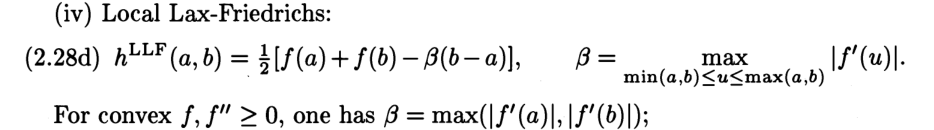

LLFflux = @(a,b) 0.5 * ( fu(a) + fu(b) - max(abs(a),abs(b)) * (b - a) );